clear
clc
format long

load data_0830

% time
tout = data2(:,1)/1000; %unit change from msec to sec

## Plant A, B, C, D: voltage&current phasor, 3 phase

for n = 1:1:length(tout)
    % plant A
    va_A(n) = data2(n,2)*exp(1i*data2(n,3)*pi/180);
    vb_A(n) = data2(n,4)*exp(1i*data2(n,5)*pi/180);
    vc_A(n) = data2(n,6)*exp(1i*data2(n,7)*pi/180);
    
    ia_A(n) = data2(n,8)*exp(1i*data2(n,9)*pi/180);
    ib_A(n) = data2(n,10)*exp(1i*data2(n,11)*pi/180);
    ic_A(n) = data2(n,12)*exp(1i*data2(n,13)*pi/180);
    
    % plant B
    va_B(n) = data2(n,14)*exp(1i*data2(n,15)*pi/180);
    vb_B(n) = data2(n,16)*exp(1i*data2(n,17)*pi/180);
    vc_B(n) = data2(n,18)*exp(1i*data2(n,19)*pi/180);
    
    ia_B(n) = data2(n,20)*exp(1i*data2(n,21)*pi/180);
    ib_B(n) = data2(n,22)*exp(1i*data2(n,23)*pi/180);
    ic_B(n) = data2(n,24)*exp(1i*data2(n,25)*pi/180);
    
    % plant C
    va_C(n) = data2(n,26)*exp(1i*data2(n,27)*pi/180);
    vb_C(n) = data2(n,28)*exp(1i*data2(n,29)*pi/180);
    vc_C(n) = data2(n,30)*exp(1i*data2(n,31)*pi/180);
    
    ia_C(n) = data2(n,32)*exp(1i*data2(n,33)*pi/180);
    ib_C(n) = data2(n,34)*exp(1i*data2(n,35)*pi/180);
    ic_C(n) = data2(n,36)*exp(1i*data2(n,37)*pi/180);
    
    % plant D
    va_D(n) = data2(n,38)*exp(1i*data2(n,39)*pi/180);
    vb_D(n) = data2(n,40)*exp(1i*data2(n,41)*pi/180);
    vc_D(n) = data2(n,42)*exp(1i*data2(n,43)*pi/180);
    
    ia_D(n) = data2(n,44)*exp(1i*data2(n,45)*pi/180);
    ib_D(n) = data2(n,46)*exp(1i*data2(n,47)*pi/180);
    ic_D(n) = data2(n,48)*exp(1i*data2(n,49)*pi/180);
    
    % plant ABCD PQ
    % S = va*conj(ia)+vb*conj(ib)+vc*conj(ic)
    % P = real(S)/10^6 in MW
    % Q = imag(S)/10^6 in MVAR
    P_A(n) = data2(n,52); Q_A(n) = data2(n,53);
    P_B(n) = data2(n,54); Q_B(n) = data2(n,55);
    P_C(n) = data2(n,56); Q_C(n) = data2(n,57);
    P_D(n) = data2(n,58); Q_D(n) = data2(n,59);
    
    % plant ABCD V
    Vpcc(n) = data2(n,61); %average(Vmag_A+Vmag_B+Vmag_C)*sqrt(3)/1000 in kV
end

## plotting

same figure as data sheet

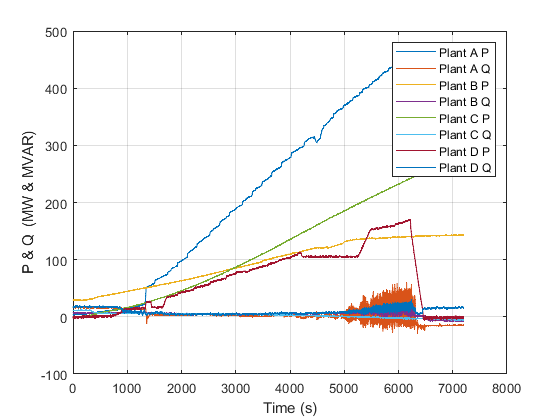

figure('Name','All plants PQ')
all_PQ = [P_A; Q_A; P_B; Q_B; P_C; Q_C; P_D; Q_D];
plot(tout, all_PQ); grid on;
legend('Plant A P','Plant A Q','Plant B P','Plant B Q','Plant C P','Plant C Q','Plant D P','Plant D Q');
xlabel('Time (s)');
ylabel('P & Q  (MW & MVAR)');

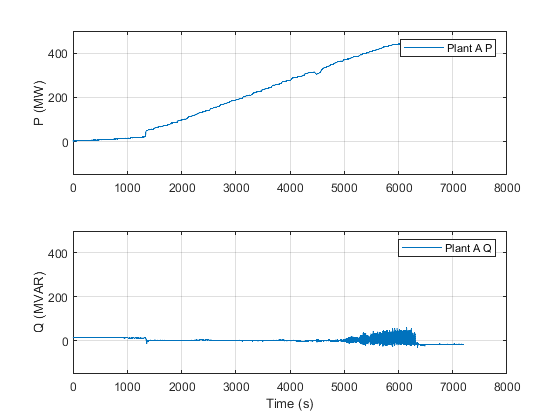


% Plant A PQ plot
figure('Name','Plant A PQ')
subplot(2,1,1)
plot(tout, P_A); grid on;
legend('Plant A P');
ylabel('P (MW)');
ylim([-150 500]);

subplot(2,1,2)
plot(tout, Q_A); grid on;
legend('Plant A Q');
ylabel('Q (MVAR)');
xlabel('Time (s)');
ylim([-150 500]);

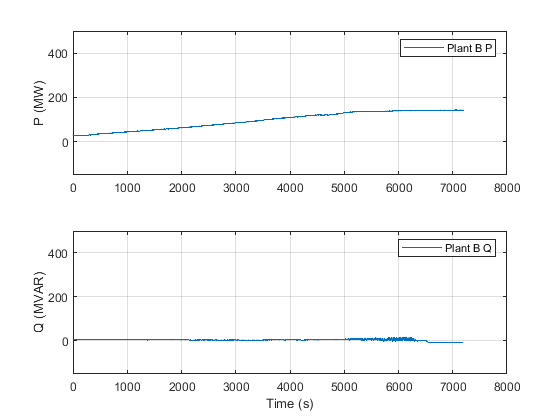


% Plant B PQ plot
figure('Name','Plant B PQ')
subplot(2,1,1)
plot(tout, P_B); grid on;
legend('Plant B P');
ylabel('P (MW)');
ylim([-150 500]);

subplot(2,1,2)
plot(tout, Q_B); grid on;
legend('Plant B Q');
ylabel('Q (MVAR)');
xlabel('Time (s)');
ylim([-150 500]);

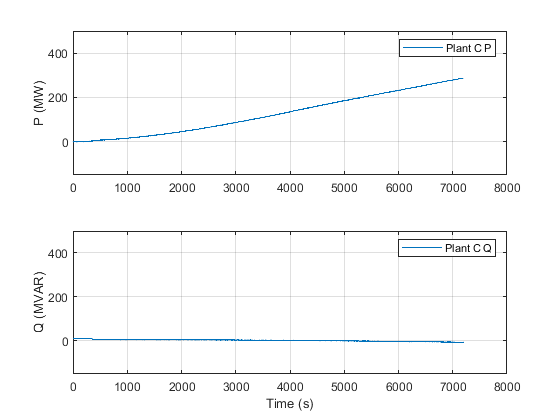


% Plant C PQ plot
figure('Name','Plant C PQ')
subplot(2,1,1)
plot(tout, P_C); grid on;
legend('Plant C P');
ylabel('P (MW)');
ylim([-150 500]);

subplot(2,1,2)
plot(tout, Q_C); grid on;
legend('Plant C Q');
ylabel('Q (MVAR)');
xlabel('Time (s)');
ylim([-150 500]);

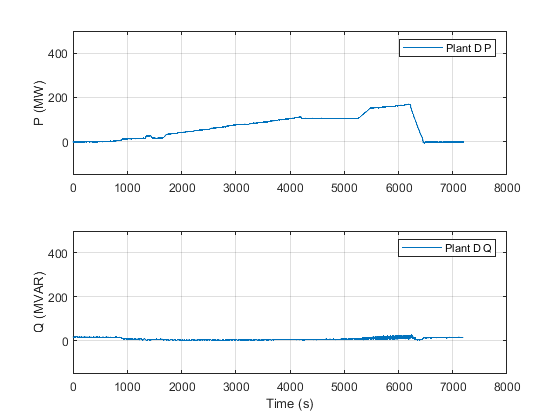


% Plant D PQ plot
figure('Name','Plant D PQ')
subplot(2,1,1)
plot(tout, P_D); grid on;
legend('Plant D P');
ylabel('P (MW)');
ylim([-150 500]);

subplot(2,1,2)
plot(tout, Q_D); grid on;
legend('Plant D Q');
ylabel('Q (MVAR)');
xlabel('Time (s)');
ylim([-150 500]);

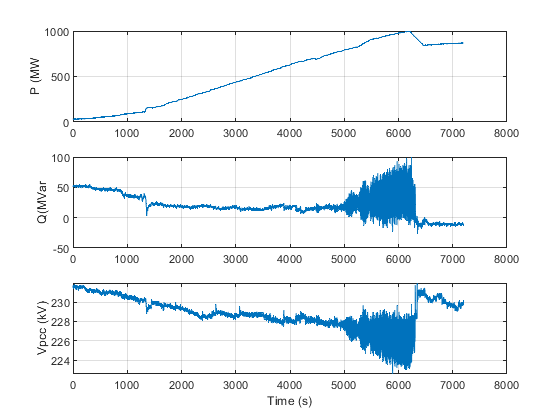


% PCC bus voltage
figure('Name','PCC bus voltage')
ax(1) = subplot(3,1,1); plot(tout, P_A+P_B+P_C+P_D ); grid on; ylabel('P (MW');
ax(2) = subplot(3,1,2); plot(tout, Q_A+Q_B+Q_C+Q_D); grid on; ylabel('Q(MVar'); 
ax(3) = subplot(3,1,3); plot(tout, Vpcc); grid on;
xlabel('Time (s)');
ylabel('Vpcc (kV)');
linkaxes(ax, 'x');

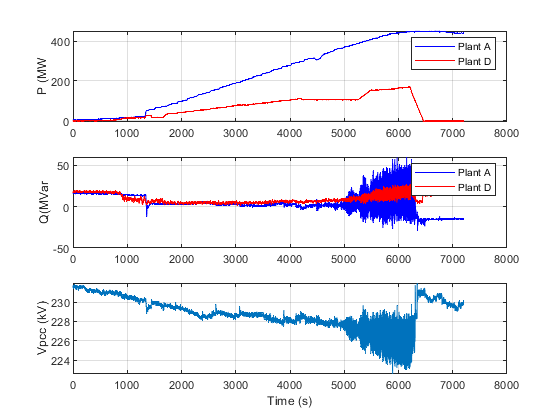



figure('Name','PCC bus voltage')
ax(1) = subplot(3,1,1); plot(tout, P_A,'b' ); grid on; ylabel('P (MW'); 
hold on; plot(tout, P_D,'r' ); legend('Plant A','Plant D'); 
ax(2) = subplot(3,1,2); plot(tout, Q_A,'b'); grid on; ylabel('Q(MVar'); 
hold on; plot(tout, Q_D,'r'); legend('Plant A','Plant D'); 
ax(3) = subplot(3,1,3); plot(tout, Vpcc); grid on;
xlabel('Time (s)');
ylabel('Vpcc (kV)');
linkaxes(ax, 'x');

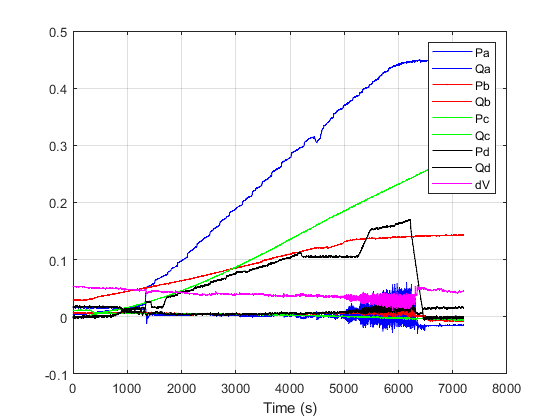



figure('Name','overall');
%yyaxis left
plot(tout, P_A/1000,'b','LineWidth',1 ); hold on; plot(tout, Q_A/1000,'b','LineWidth',0.25);
plot(tout, P_B/1000,'r' ,'LineWidth',1 ); hold on; plot(tout, Q_B/1000,'r','LineWidth',0.25);
plot(tout, P_C/1000,'g' ,'LineWidth',1 ); hold on; plot(tout, Q_C/1000,'g','LineWidth',0.25);
plot(tout, P_D/1000,'k','LineWidth',1  ); hold on; plot(tout, Q_D/1000,'k','LineWidth',0.25);
%yyaxis right
plot(tout, Vpcc/220-1,'m');grid on;
xlabel('Time (s)');
legend( ...
    'Pa','Qa','Pb','Qb','Pc','Qc','Pd','Qd','dV');